## **Soft Manipulator Actuation** 

We created a 0.9m soft beam with radius linearly varying from 3cm to 1cm. The link consists of 2 divisions, the first division is 0.4m long and the second is 0.5m long.

Torsion (x-axis) and bending (y- and z-axis) modes of deformation are enabled with a quadratic strain basis.

SorosimLink (`L1`) and SorosimLinkage (`T1`) are saved in `SoftManipulator.mat`

load('SoftManipulator.mat')

To see the properties of `L1`

L1

L1 =   SorosimLink with properties:

    jointtype: 'N'
     linktype: 's'
           CS: 'C'
         npie: 3
           lp: {[0.4000]  [0.5000]}
            L: 0.9000
            r: {@(X1)X1.*(-8.9e-3)+3.0./1.0e+2  @(X1)X1.*(-1.11e-2)+2.11e-2}
            h: {[]  []}
            w: {[]  []}
            a: {[]  []}
            b: {[]  []}
           gi: {[4×4 double]  [4×4 double]}
           gf: {[4×4 double]  [4×4 double]}
            E: 1000000
          Poi: 0.5000
            G: 3.3333e+05
          Eta: 10000
          Rho: 1000
           Kj: []
           Dj: []
            M: []
          n_l: 25
          n_r: 18
        color: [0.6797 0.6551 0.1626]
          CPF: 0
       PlotFn: @(g)CustomShapePlot(g)
       Lscale: 0.1365


To see the properties of S`1`

T1

T1 =   SorosimLinkage with properties:

                   N: 1
                ndof: 18
                nsig: 15
              VLinks: [1×1 SorosimLink]
           LinkIndex: 1
            CVTwists: {[1×3 SorosimTwist]}
               iLpre: 0
               g_ini: [4×4 double]
             Z_order: 4
                nCLj: []
                iACL: []
                iCLB: []
          VTwistsCLj: []
               gACLj: []
               gBCLj: []
        CLprecompute: [1×1 struct]
                T_BS: []
             Gravity: 0
                   G: 0
          PointForce: 0
       FollowerForce: []
                  np: []
              Fp_loc: []
              Fp_vec: []
                CEFP: 0
             M_added: []
            Actuated: 1
                nact: 4
                Bqj1: []
              n_jact: 0
              i_jact: []
             i_jactq: []
    WrenchControlled: []
              n_sact: 

To see the problem definition:

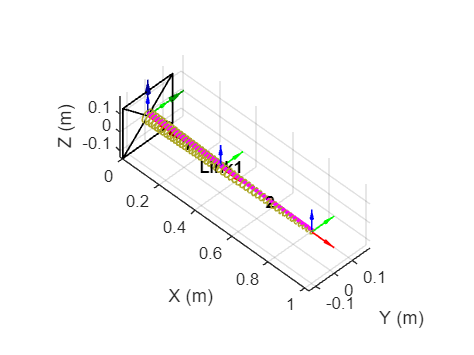

T1.plotq0

The result should be:

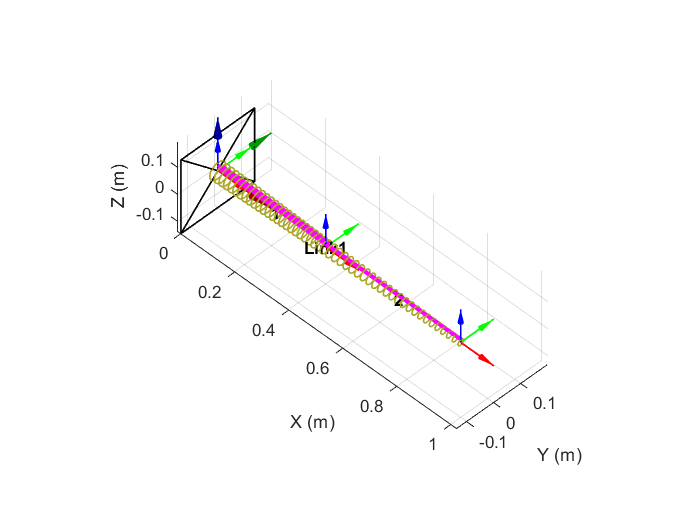

The beam is rigidly fixed at one end and can be subjected to actuation forces.

### **Static equilibirum analysis**

For statics equilibirum analysis type:

Time-advancing

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0         19         3.87917e+13                        4.51e+13              1
     1         38         7.58581e+12              1         2.58e+12              1
     2         57         1.44142e+12            2.5         7.87e+12            2.5
     3         76         1.45418e+11           6.25         2.46e+11           6.25
     4         95         0.000192667        7.21058         8.68e+03           15.6
     5        114         2.31689e-17    1.14879e-06          0.00491             18
     6        133         7.70372e-20    7.45822e-13         0.000757             18

Equation solved, solver stalled.

fsolve stopped because the relative 

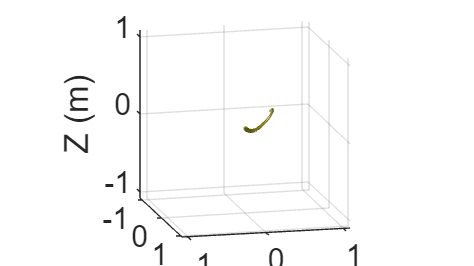

q=T1.statics;

You will be prompted to enter the actuation force in the command window. Enter -5, -10, -15, -20 N as the input actuation forces into cables 1, 2, 3 and 4 respectively. 

A dialog box will then pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

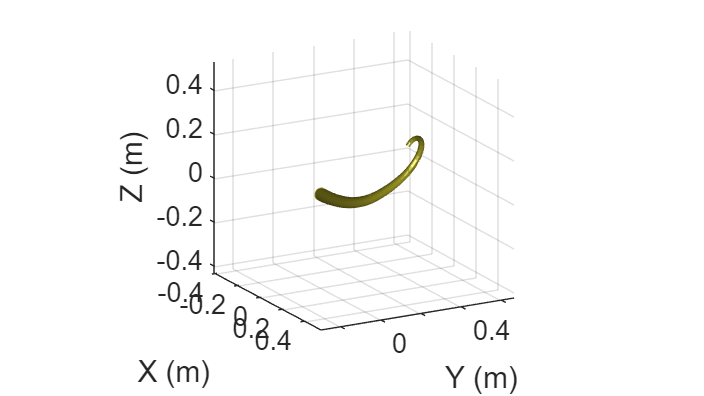

### **Dynamics**

For dynamics problem, type:

    0.0032

    0.0078

    0.0478

    0.1071

    0.1354

    0.1620

    0.1921

    0.2495

    0.2634

    0.2828

    0.2916

    0.3947

    0.4178

    0.4404

    0.4970

    0.5316

    0.5666

    0.6249

    0.6531

    0.6916

    0.7505

    0.7796

    0.9040

    1.0334

    1.1503

    1.2466

    1.3667

    1.4977

    1.6063

    1.6761

    1.7839

    1.9134

    2.0480

    2.1759

    2.2758

    2.3965

    2.5163

    2.6183

    2.7062

    2.7927

    2.9479

    3.0494

    3.1419

    3.2627

    3.3901

    3.4375

    3.6061

    3.7059

    3.7875

    3.8957

    3.9538

    4.0452

    4.1550

    4.2527

    4.2867

    4.4312

    4.5616

    4.6730

    4.7813

    4.9137

Elapsed time is 22.821974 seconds.


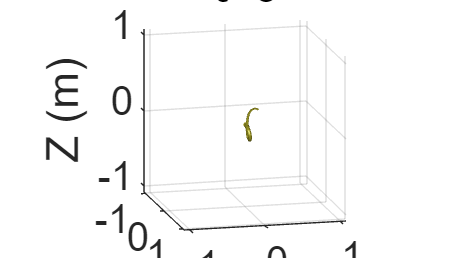

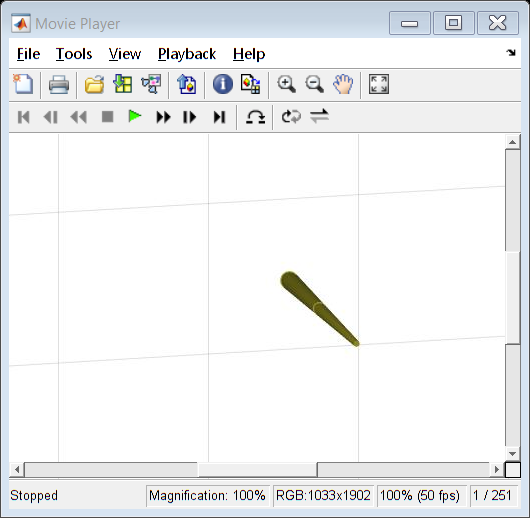

[t,qqd]=T1.dynamics([],'ode15s');

The actuation input to the cables can be input by the user as a function of t in the command window.

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will then be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

Dynamic compulation will take some time.

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.avi` will be saved in the folder.